### ABV Nitrogen Budget

% ASSUMPTIONS / INPUTS TO VERIFY

clear; clc; close all;

% Unit conversions
ft2m = 0.3048; in2m = 0.0254; psi2Pa = 6894.76; g0 = 9.81;

% ABV parameters
m_abv = 12.7;
abv_length = 1.125 * ft2m;
abv_width  = 1.125 * ft2m;
n_thrusters_lin = 2;
n_thrusters_rot = 2;
r_arm = 0.1235;
r_mech_mount = abv_length/2;
M_crit_tank = 1.695 * 9.81 * (26*0.0254);         % N*m, ARL tank-side test
m_ground = M_crit_tank / (9.81 * r_mech_mount);   % kg, grounding limit

% Thruster / valve
d_orifice = (1/16) * in2m;
Cd = 0.75;
P_reg_psig_sweep = [30 60 80 100];
P_reg_psig_nom = 60;
F_config = 0.1;

% Nitrogen gas
gam = 1.4; R_N2 = 296.8; T0 = 293.15; P_amb = 101325;

% Tank
V_tank = 48 * in2m^3;
P_fill_psig = [3000 4500];
Z_fill = 1.0;
P_dropout_margin_psi = 100;

% Requirements
v_min = 0.05; v_max = 0.10;
angular_offset = deg2rad(4);

% Run profile (VERIFY against the planned test procedure)
d_setup   = 1.0;
v_setup   = v_max;
d_approach = 1.5;
v_cmd     = v_max;
d_backoff = 0.30;
v_backoff = v_min;
t_dwell   = 10;
table_slope = 0.1e-3;
control_margin = 2.0;

mdot_pads_sweep = [0 0.5 1.0 2.0] * 1e-3;

% GSA answer and campaign target
t_gsa = 120;
n_runs_needed = 20;

% Mass sweep
m_payload = linspace(0, 10, 21);
mass_report = [0 5 10];

### Thrust and mass flow per thruster

A_orf = pi * d_orifice^2 / 4;
nP = numel(P_reg_psig_sweep);
P_reg_abs = P_reg_psig_sweep * psi2Pa + P_amb;
F_orf = zeros(1,nP); mdot_orf = zeros(1,nP); choked = false(1,nP);
for k = 1:nP
    [F_orf(k), mdot_orf(k), choked(k)] = orifice_thrust(P_reg_abs(k), A_orf, Cd, gam, R_N2, T0, P_amb);
end
c_orf = F_orf ./ mdot_orf;     % m/s, effective exhaust velocity
iNom = find(P_reg_psig_sweep == P_reg_psig_nom, 1);
if isempty(iNom), error('P_reg_psig_nom must be in P_reg_psig_sweep.'); end

fprintf('\n THRUSTER MODEL (per thruster) \n');


 THRUSTER MODEL (per thruster) 


fprintf('%-12s %8s %11s %9s %8s %7s\n', 'Setpoint', 'F (N)', 'mdot (g/s)', 'c (m/s)', 'Isp (s)', 'Choked');

Setpoint        F (N)  mdot (g/s)   c (m/s)  Isp (s)  Choked


for k = 1:nP
    if choked(k), s = 'yes'; else, s = 'NO'; end
    fprintf('%6d psig %8.3f %11.2f %9.0f %8.0f %7s\n', P_reg_psig_sweep(k), F_orf(k), ...
        mdot_orf(k)*1e3, c_orf(k), c_orf(k)/g0, s);
end

    30 psig    0.430        1.06       405       41     yes
    60 psig    0.819        1.77       461       47     yes
    80 psig    1.078        2.25       479       49     yes
   100 psig    1.338        2.73       491       50     yes


fprintf('Config placeholder %.2f N is %.1fx below the orifice value at %d psig.\n', ...
    F_config, F_orf(iNom)/F_config, P_reg_psig_nom);

Config placeholder 0.10 N is 8.2x below the orifice value at 60 psig.


### Tank inventory

nF = numel(P_fill_psig);
m_full = (P_fill_psig*psi2Pa + P_amb) * V_tank / (Z_fill * R_N2 * T0);   % kg
m_resid = zeros(1,nP); m_usable = zeros(nP,nF);
for k = 1:nP
    m_resid(k) = (P_reg_abs(k) + P_dropout_margin_psi*psi2Pa) * V_tank / (R_N2 * T0);
    m_usable(k,:) = max(m_full - m_resid(k), 0);
end

fprintf('\n TANK INVENTORY (48 ci = %.3f L) \n', V_tank*1e3);


 TANK INVENTORY (48 ci = 0.787 L) 


for f = 1:nF
    fprintf('%d psi fill: %.0f g full, %.0f g usable at %d psig regulator\n', ...
        P_fill_psig(f), m_full(f)*1e3, m_usable(iNom,f)*1e3, P_reg_psig_nom);
end

3000 psi fill: 188 g full, 177 g usable at 60 psig regulator
4500 psi fill: 281 g full, 271 g usable at 60 psig regulator


### Propellant and time per run

m_total = m_abv + m_payload;
nM = numel(m_payload);
I_base = (1/12) * m_abv * (abv_length^2 + abv_width^2);
I_z = I_base + (m_abv .* m_payload * r_mech_mount^2) ./ m_total;   % parallel axis

% Index 1..nP = orifice model at each setpoint; nP+1 = config placeholder
F_cases = [F_orf, F_config];
c_cases = [c_orf, c_orf(iNom)];
nC = numel(F_cases);

t_run = zeros(nC,nM); m_run_thr = zeros(nC,nM);
for c = 1:nC
    for i = 1:nM
        a  = n_thrusters_lin * F_cases(c) / m_total(i);
        al = n_thrusters_rot * F_cases(c) * r_arm / I_z(i);

        t_setup = move_time(d_setup, v_setup, a);
        t_slew  = 2 * sqrt(angular_offset / al);
        s_acc   = v_cmd^2 / (2*a);
        if s_acc <= d_approach
            t_appr = v_cmd/a + (d_approach - s_acc)/v_cmd;
        else
            t_appr = sqrt(2*d_approach/a);
        end
        t_back = move_time(d_backoff, v_backoff, a);
        t_run(c,i) = t_setup + t_slew + t_appr + t_back + t_dwell;

        dv_lin = control_margin * (2*v_setup + v_cmd + 2*v_backoff) + g0*table_slope*t_run(c,i);
        m_lin  = m_total(i) * dv_lin / c_cases(c);
        m_rot  = control_margin * n_thrusters_rot * (F_cases(c)/c_cases(c)) * t_slew;
        m_run_thr(c,i) = m_lin + m_rot;
    end
end

fprintf('\n THRUSTER N2 PER RUN (nominal %d psig) \n', P_reg_psig_nom);


 THRUSTER N2 PER RUN (nominal 60 psig) 


fprintf('%8s %11s %12s %14s\n', 'm_pay', 't_run (s)', 'N2/run (g)', 'runs/fill*');

   m_pay   t_run (s)   N2/run (g)     runs/fill*


for mr = mass_report
    [~, i] = min(abs(m_payload - mr));
    fprintf('%8.1f %11.1f %12.1f %14s\n', m_payload(i), t_run(iNom,i), m_run_thr(iNom,i)*1e3, ...
        sprintf('%d / %d', floor(m_usable(iNom,1)/m_run_thr(iNom,i)), floor(m_usable(iNom,2)/m_run_thr(iNom,i))));
end

     0.0        43.1         27.3          6 / 9
     5.0        43.9         37.3          4 / 7
    10.0        44.5         46.9          3 / 5


fprintf('* thrusters only, %d / %d psi fill\n', P_fill_psig(1), P_fill_psig(2));

* thrusters only, 3000 / 4500 psi fill


fprintf('With the %.2f N placeholder, run time at 10 kg is %.1f s (N2 per run unchanged).\n', ...
    F_config, t_run(end,end));

With the 0.10 N placeholder, run time at 10 kg is 65.8 s (N2 per run unchanged).


### Scenario A: a run lasts under 2 minutes

nB = numel(mdot_pads_sweep);
runsA = zeros(nB, nF); fillsA = zeros(nB, nF);
fprintf('\n SCENARIO A (10 kg payload, nominal %d psig) \n', P_reg_psig_nom);


 SCENARIO A (10 kg payload, nominal 60 psig) 


fprintf('%12s', 'pad bleed');

   pad bleed

for f = 1:nF, fprintf(' %20s', sprintf('%d psi runs|fills', P_fill_psig(f))); end

  3000 psi runs|fills  4500 psi runs|fills

fprintf('\n');
for b = 1:nB
    m_run = m_run_thr(iNom,end) + mdot_pads_sweep(b) * t_run(iNom,end);
    fprintf('%8.1f g/s', mdot_pads_sweep(b)*1e3);
    for f = 1:nF
        runsA(b,f)  = floor(m_usable(iNom,f) / m_run);
        fillsA(b,f) = ceil(n_runs_needed * m_run / m_usable(iNom,f));
        fprintf(' %20s', sprintf('%d | %d', runsA(b,f), fillsA(b,f)));
    end
    fprintf('\n');
end

     0.0 g/s

                3 | 6                5 | 4

     0.5 g/s

                2 | 8                3 | 6

     1.0 g/s

               1 | 11                2 | 7

     2.0 g/s

               1 | 16               1 | 11

fprintf('fills = tank fills needed for %d runs\n', n_runs_needed);

fills = tank fills needed for 20 runs


if any(t_run(iNom,:) > t_gsa)
    fprintf('NOTE: modeled run exceeds 2 min at some masses; the run profile may be longer than the GSA''s runs.\n');
end

### Scenario B: a full tank lasts about 2 minutes

mdot_thr_avg = m_run_thr(iNom,end) / t_run(iNom,end);
fprintf('\n SCENARIO B (10 kg payload, nominal %d psig) \n', P_reg_psig_nom);


 SCENARIO B (10 kg payload, nominal 60 psig) 


for f = 1:nF
    mdot_implied = m_usable(iNom,f) / t_gsa;
    runsB = floor(t_gsa / t_run(iNom,end));
    fprintf('%d psi fill: implied draw %.2f g/s; thrusters %.2f g/s; unexplained %.2f g/s; runs/fill %d; fills for %d runs %d\n', ...
        P_fill_psig(f), mdot_implied*1e3, mdot_thr_avg*1e3, (mdot_implied - mdot_thr_avg)*1e3, ...
        runsB, n_runs_needed, ceil(n_runs_needed / max(runsB,1)));
end

3000 psi fill: implied draw 1.48 g/s; thrusters 1.05 g/s; unexplained 0.42 g/s; runs/fill 2; fills for 20 runs 10
4500 psi fill: implied draw 2.25 g/s; thrusters 1.05 g/s; unexplained 1.20 g/s; runs/fill 2; fills for 20 runs 10


### Sensitivity to control margin

cm_sweep = 1:0.25:3;
m_run_cm = zeros(size(cm_sweep));
for j = 1:numel(cm_sweep)
    i = nM;   % 10 kg
    dv = cm_sweep(j) * (2*v_setup + v_cmd + 2*v_backoff) + g0*table_slope*t_run(iNom,i);
    al = n_thrusters_rot * F_orf(iNom) * r_arm / I_z(i);
    m_run_cm(j) = m_total(i)*dv/c_orf(iNom) + cm_sweep(j)*n_thrusters_rot*mdot_orf(iNom)*2*sqrt(angular_offset/al);
end
fprintf('\n CONTROL-MARGIN SENSITIVITY (10 kg, %d psi fill, no pad bleed) \n', P_fill_psig(1));


 CONTROL-MARGIN SENSITIVITY (10 kg, 3000 psi fill, no pad bleed) 


for j = 1:numel(cm_sweep)
    fprintf('margin %.2f: %.1f g/run, %d runs/fill\n', cm_sweep(j), m_run_cm(j)*1e3, floor(m_usable(iNom,1)/m_run_cm(j)));
end

margin 1.00: 24.5 g/run, 7 runs/fill
margin 1.25: 30.1 g/run, 5 runs/fill
margin 1.50: 35.7 g/run, 4 runs/fill
margin 1.75: 41.3 g/run, 4 runs/fill
margin 2.00: 46.9 g/run, 3 runs/fill
margin 2.25: 52.5 g/run, 3 runs/fill
margin 2.50: 58.0 g/run, 3 runs/fill
margin 2.75: 63.6 g/run, 2 runs/fill
margin 3.00: 69.2 g/run, 2 runs/fill


### Measured consumption from logged tank pressure

P_before_psig = [];   % e.g. [2950 2610 2280]
P_after_psig  = [];   % e.g. [2610 2280 1960]
t_run_logged  = [];   % s, measured run durations (optional, same length)

if ~isempty(P_before_psig)
    dP = (P_before_psig - P_after_psig) * psi2Pa;
    m_used = dP * V_tank / (R_N2 * T0);
    fprintf('\n MEASURED N2 PER RUN \n');
    for r = 1:numel(m_used)
        fprintf('Run %d: %.1f g\n', r, m_used(r)*1e3);
    end
    fprintf('Mean %.1f g/run vs. model %.1f g/run (nominal, payload sweep max)\n', ...
        mean(m_used)*1e3, m_run_thr(iNom,end)*1e3);
    if ~isempty(t_run_logged)
        fprintf('Mean draw %.2f g/s over logged run time\n', mean(m_used ./ t_run_logged)*1e3);
    end
else
    fprintf('\nNo logged tank pressures yet; enter P_before_psig / P_after_psig above.\n');
end


No logged tank pressures yet; enter P_before_psig / P_after_psig above.


## Test campaign allocation (item 6.2)

radial_offset   = 0.10;
m_pay_alloc = 2.3866*0.45359*1.25;
fill_alloc = 1;
mdot_pads_alloc = 0;
n_checkout      = 3;
retry_factor    = 1.25;
cycles_per_durability = 5;

test_name = {'Checkout', 'Roll (SYS.09)', 'Velocity v_min', 'Velocity v_max', ...
             'Radial (SYS.07)', 'Angular (SYS.08)', 'Durability'};
n_test   = [n_checkout 2 1 1 2 2 2];
lat_move = [0 0 0 0 radial_offset 0 0];
yaw_move = [0 0 0 0 0 angular_offset 0];
v_test   = [v_max v_max v_min v_max v_max v_max v_max];
n_cyc    = [1 1 1 1 1 1 cycles_per_durability];

P.m  = m_abv + m_pay_alloc;
P.I  = (1/12)*m_abv*(abv_length^2 + abv_width^2) + m_abv*m_pay_alloc*r_mech_mount^2 / P.m;
P.F  = F_orf(iNom);  P.c = c_orf(iNom);
P.n_lin = n_thrusters_lin;  P.n_rot = n_thrusters_rot;  P.r_arm = r_arm;
P.d_setup = d_setup;  P.v_setup = v_setup;  P.d_approach = d_approach;
P.d_backoff = d_backoff;  P.v_backoff = v_backoff;  P.t_dwell = t_dwell;
P.cm = control_margin;  P.slope = table_slope;  P.g0 = g0;  P.mdot_pads = mdot_pads_alloc;

nT = numel(test_name);
g_run = zeros(1,nT); t_test = zeros(1,nT);
for k = 1:nT
    [g_run(k), t_test(k)] = run_gas(P, lat_move(k), yaw_move(k), v_test(k), n_cyc(k));
end
g_total = n_test .* g_run * retry_factor;
m_use = m_usable(iNom, fill_alloc);

fprintf('\n TEST CAMPAIGN ALLOCATION (%.1f kg mechanism, %d psig, %d psi fill, %.0f g usable) \n', ...
    m_pay_alloc, P_reg_psig_nom, P_fill_psig(fill_alloc), m_use*1e3);


 TEST CAMPAIGN ALLOCATION (1.4 kg mechanism, 60 psig, 3000 psi fill, 177 g usable) 


fprintf('%-18s %6s %10s %10s %12s %8s\n', 'Test', 'Count', 'g / test', 's / test', 'Total (g)*', '% total');

Test                Count   g / test   s / test   Total (g)*  % total


for k = 1:nT
    fprintf('%-18s %6d %10.1f %10.1f %12.1f %8.1f\n', test_name{k}, n_test(k), g_run(k)*1e3, ...
        t_test(k), g_total(k)*1e3, 100*g_total(k)/sum(g_total));
end

Checkout                3       25.6       42.7         96.2     16.5
Roll (SYS.09)           2       25.6       42.7         64.1     11.0
Velocity v_min          1       23.0       57.5         28.8      4.9
Velocity v_max          1       25.6       42.7         32.1      5.5
Radial (SYS.07)         2       37.9       44.6         94.7     16.2
Angular (SYS.08)        2       30.1       43.3         75.3     12.9
Durability              2       76.7      122.1        191.9     32.9


fprintf('%-18s %6d %10s %10s %12.1f\n', 'TOTAL', sum(n_test), '', '', sum(g_total)*1e3);

TOTAL                  13                              582.9


fprintf('* includes %.0f%% retry reserve\n', 100*(retry_factor-1));

* includes 25% retry reserve


for f = 1:nF
    fprintf('Fills needed at %d psi: %d\n', P_fill_psig(f), ceil(sum(g_total) / m_usable(iNom,f)));
end

Fills needed at 3000 psi: 4
Fills needed at 4500 psi: 3



% Fill schedule: keep each test instance inside one fill, in test order
fprintf('\n FILL SCHEDULE (%d psi fills, no retries) \n', P_fill_psig(fill_alloc));


 FILL SCHEDULE (3000 psi fills, no retries) 


fill_no = 1; remaining = m_use; fill_list = '';
for k = 1:nT
    for j = 1:n_test(k)
        if g_run(k) > m_use
            fprintf('WARNING: one %s test (%.0f g) exceeds a full fill -- refill mid-test or cut cycles\n', ...
                test_name{k}, g_run(k)*1e3);
        end
        if g_run(k) > remaining
            fprintf('Fill %d: %s\n', fill_no, fill_list(1:end-2));
            fill_no = fill_no + 1; remaining = m_use; fill_list = '';
        end
        remaining = remaining - g_run(k);
        fill_list = [fill_list, sprintf('%s #%d, ', test_name{k}, j)];
    end
end

Fill 1: Checkout #1, Checkout #2, Checkout #3, Roll (SYS.09) #1, Roll (SYS.09) #2, Velocity v_min #1, Velocity v_max #1
Fill 2: Radial (SYS.07) #1, Radial (SYS.07) #2, Angular (SYS.08) #1, Angular (SYS.08) #2


fprintf('Fill %d: %s\n', fill_no, fill_list(1:end-2));

Fill 3: Durability #1, Durability #2


### Plots

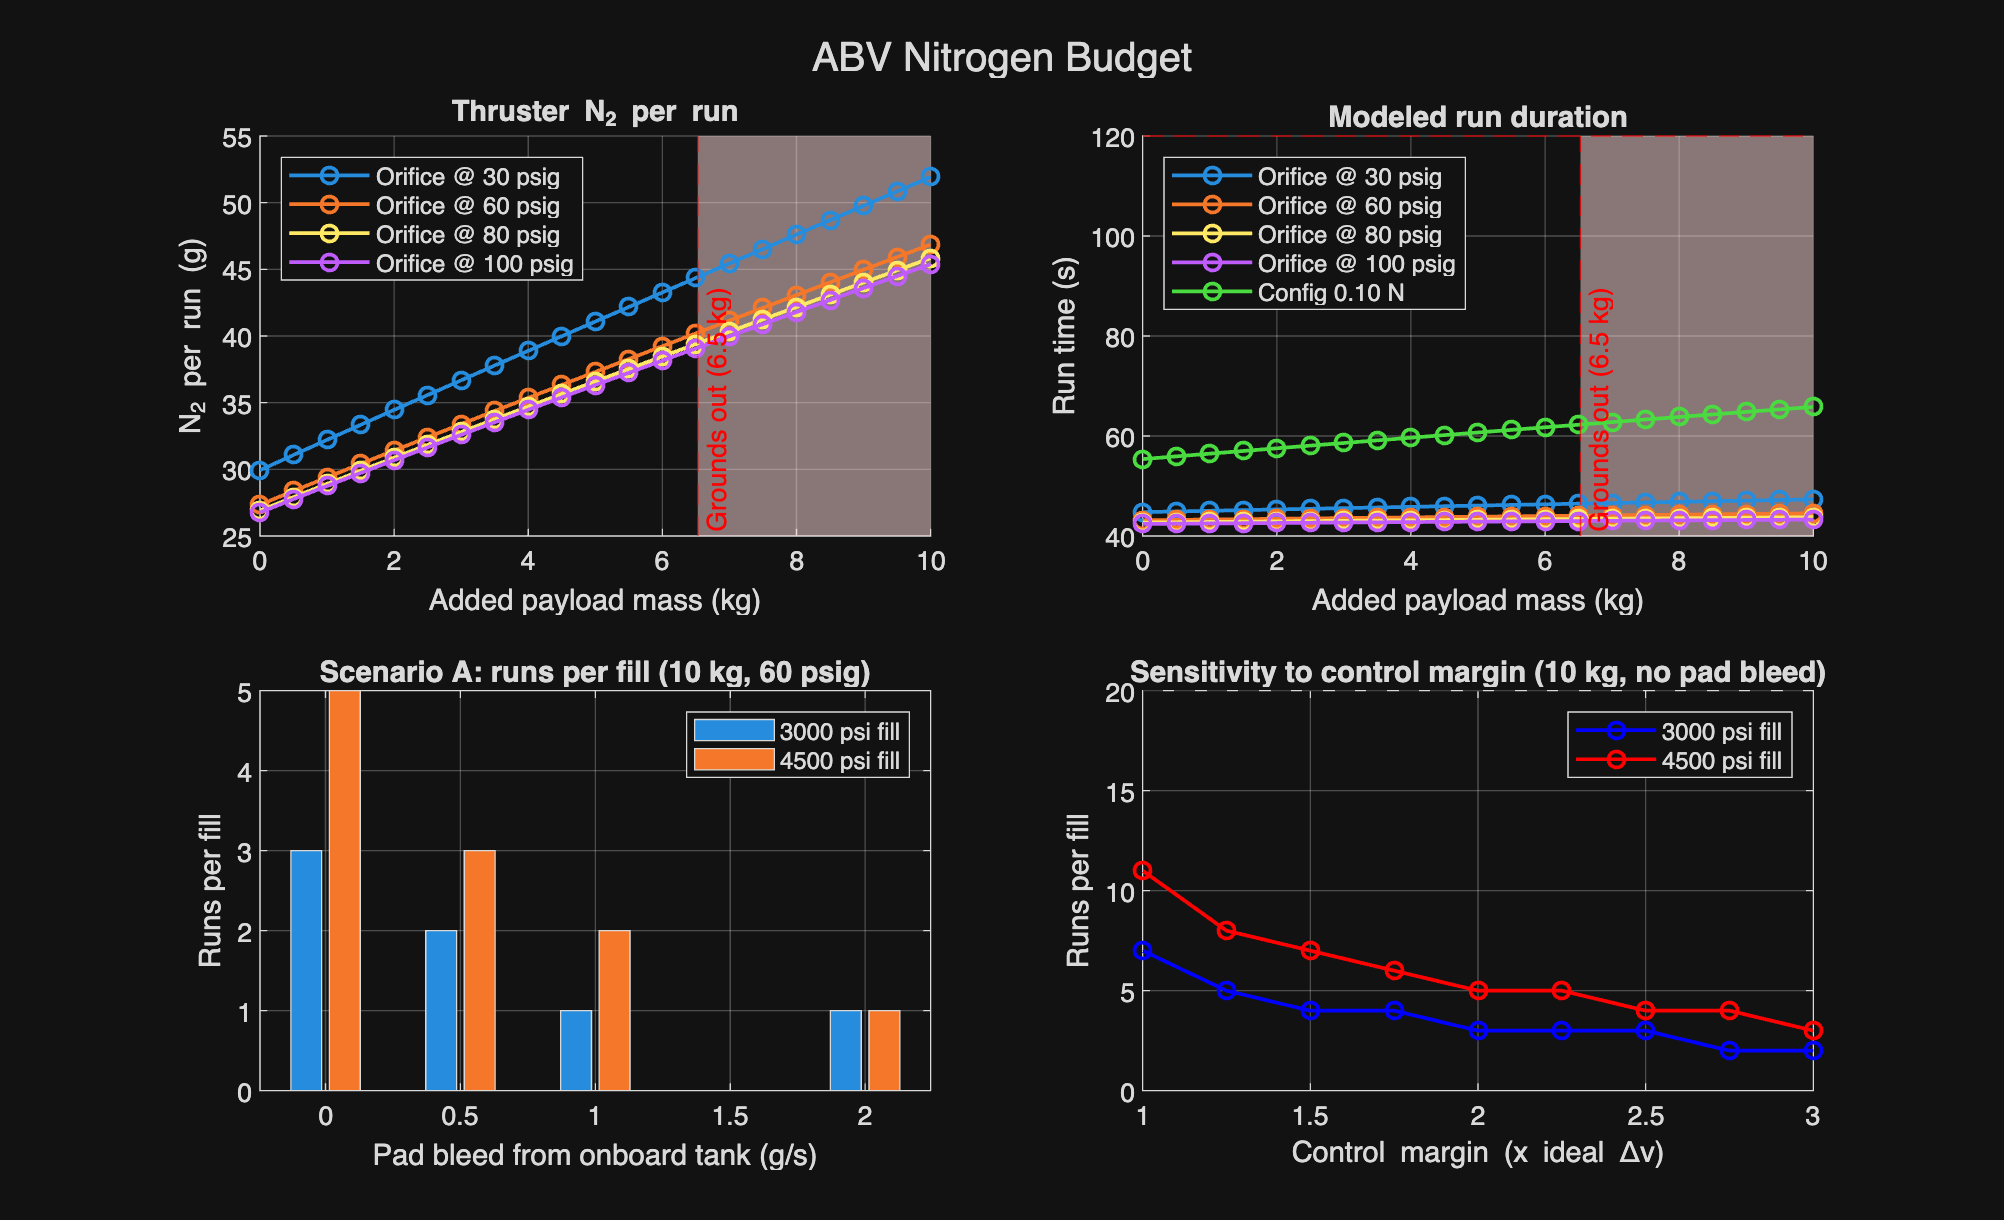

cols = lines(nC);
leg = [arrayfun(@(p) sprintf('Orifice @ %d psig', p), P_reg_psig_sweep, 'UniformOutput', false), ...
       {sprintf('Config %.2f N', F_config)}];

figure('Name', 'ABV Nitrogen Budget', 'Position', [100 100 1150 700]);

subplot(2,2,1); hold on;
for c = 1:nP
    plot(m_payload, m_run_thr(c,:)*1e3, '-o', 'Color', cols(c,:), 'LineWidth', 1.4);
end
xlabel('Added payload mass (kg)'); ylabel('N_2 per run (g)');
title('Thruster N_2 per run'); legend(leg(1:nP), 'Location', 'northwest'); grid on;
mark_ground_limit(m_ground);

subplot(2,2,2); hold on;
for c = 1:nC
    plot(m_payload, t_run(c,:), '-o', 'Color', cols(c,:), 'LineWidth', 1.4);
end
yline(t_gsa, 'r--', 'GSA: 2 min');
xlabel('Added payload mass (kg)'); ylabel('Run time (s)');
title('Modeled run duration'); legend(leg, 'Location', 'northwest'); grid on;
mark_ground_limit(m_ground);

subplot(2,2,3);
bar(mdot_pads_sweep*1e3, runsA);
xlabel('Pad bleed from onboard tank (g/s)'); ylabel('Runs per fill');
legend(arrayfun(@(p) sprintf('%d psi fill', p), P_fill_psig, 'UniformOutput', false));
title(sprintf('Scenario A: runs per fill (10 kg, %d psig)', P_reg_psig_nom)); grid on;

subplot(2,2,4);
plot(cm_sweep, floor(m_usable(iNom,1)./m_run_cm), 'b-o', cm_sweep, floor(m_usable(iNom,2)./m_run_cm), 'r-o', 'LineWidth', 1.4);
yline(n_runs_needed, 'k--', sprintf('%d runs', n_runs_needed));
xlabel('Control margin (x ideal \Deltav)'); ylabel('Runs per fill');
legend(arrayfun(@(p) sprintf('%d psi fill', p), P_fill_psig, 'UniformOutput', false));
title('Sensitivity to control margin (10 kg, no pad bleed)'); grid on;

sgtitle('ABV Nitrogen Budget');

### Local functions

function [F, mdot, isChoked] = orifice_thrust(p0, A, Cd, gam, R, T0, pa)
% Thrust and mass flow of gas exhausting through an orifice to ambient.
pr_crit = (2/(gam+1))^(gam/(gam-1));
Aeff = Cd * A;
if pa/p0 <= pr_crit
    isChoked = true;
    mdot  = Aeff * p0 * sqrt(gam/(R*T0)) * (2/(gam+1))^((gam+1)/(2*(gam-1)));
    vstar = sqrt(gam * R * T0 * 2/(gam+1));
    F = mdot * vstar + (p0*pr_crit - pa) * Aeff;
else
    isChoked = false;
    pr   = pa/p0;
    mdot = Aeff * p0 * sqrt(2*gam/((gam-1)*R*T0) * (pr^(2/gam) - pr^((gam+1)/gam)));
    ve   = sqrt(2*gam/(gam-1) * R * T0 * (1 - pr^((gam-1)/gam)));
    F = mdot * ve;
end
end

function t = move_time(d, v, a)
% Rest-to-rest move: trapezoidal if it reaches v, triangular otherwise.
if d <= 0
    t = 0;
elseif d >= v^2/a
    t = d/v + v/a;
else
    t = 2*sqrt(d/a);
end
end

function [m_gas, t] = run_gas(P, d_lat, yaw, v_c, n_cycles)
% N2 used and time for one test instance: setup move, optional lateral
% move and yaw slew, then n_cycles of approach + back-off.
a  = P.n_lin * P.F / P.m;
al = P.n_rot * P.F * P.r_arm / P.I;
dv = 0; t = 0; m_rot = 0;
[tt, vp] = move_profile(P.d_setup, P.v_setup, a);  t = t + tt;  dv = dv + 2*vp;
if d_lat > 0
    [tt, vp] = move_profile(d_lat, P.v_setup, a);  t = t + tt;  dv = dv + 2*vp;
end
if yaw > 0
    ts = 2*sqrt(yaw/al);  t = t + ts;
    m_rot = P.n_rot * (P.F/P.c) * ts;
end
for k = 1:n_cycles
    if k == 1, d = P.d_approach; else, d = P.d_backoff; end
    s_acc = v_c^2 / (2*a);
    if s_acc <= d
        t = t + v_c/a + (d - s_acc)/v_c;  dv = dv + v_c;
    else
        t = t + sqrt(2*d/a);  dv = dv + sqrt(2*a*d);
    end
    [tt, vp] = move_profile(P.d_backoff, P.v_backoff, a);  t = t + tt;  dv = dv + 2*vp;
end
t = t + P.t_dwell * n_cycles;
dv = P.cm * dv + P.g0 * P.slope * t;
m_gas = P.m * dv / P.c + P.cm * m_rot + P.mdot_pads * t;
end

function [t, v_pk] = move_profile(d, v, a)
% Rest-to-rest move: time and peak speed (trapezoidal or triangular).
if d <= 0
    t = 0; v_pk = 0;
elseif d >= v^2/a
    t = d/v + v/a; v_pk = v;
else
    t = 2*sqrt(d/a); v_pk = sqrt(a*d);
end
end

function mark_ground_limit(m_lim)
% Shade payload masses past the grounding limit on the current axes.
xl = xlim; yl = ylim;
if m_lim < xl(2)
    hold on;
    h = patch([m_lim xl(2) xl(2) m_lim], [yl(1) yl(1) yl(2) yl(2)], [1 0.85 0.85], ...
        'EdgeColor', 'none', 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
    uistack(h, 'bottom');
    xline(m_lim, 'r--', sprintf('Grounds out (%.1f kg)', m_lim), ...
        'HandleVisibility', 'off', 'LabelVerticalAlignment', 'bottom');
    xlim(xl); ylim(yl);
end
end